### **Método De Gauss-Jacobi**


$$x^{k+1} =\Phi(x^{k})$$
 


$$x_{1}^{(k+1)} = \frac{1}{a_{11}} ( b_{1} - a_{12}x_{2}^{(k)} - a_{13}x_{3}^{(k)} - \cdots - a_{1n}x_{n}^{(k)})\\
x_{2}^{(k+1)} = \frac{1}{a_{22}} ( b_{2} - a_{21}x_{1}^{(k)} - a_{23}x_{3}^{(k)} - \cdots - a_{2n}x_{n}^{(k)})\\
  x_{3}^{(k+1)} = \frac{1}{a_{33}} ( b_{3} - a_{31}x_{1}^{(k)} - a_{32}x_{2}^{(k)} - \cdots - a_{3n}x_{n}^{(k)})\\
  \vdots               = \vdots \\
  x_{n}^{(k+1)}=  \frac{1}{a_{nn}} ( b_{n} - a_{n1}x_{1}^{(k)} - a_{n2}x_{2}^{(k)} - \cdots - a_{n,n-1}x_{n-1}^{(k)})
$$


Vamos encontrar a solução aproximada do sistema 


$$\begin{cases}
5x_{1} + x_{2} + x_{3} = 5\\
3x_{1} + 4x_{2} + x_{3} = 6\\
2x_{1} + 3x_{2} + 6x_{3} = 0
\end{cases}$$


com chute inicial $x^{0} = (0,0,0)$ e $\epsilon=0.05$.

Graficamente, 

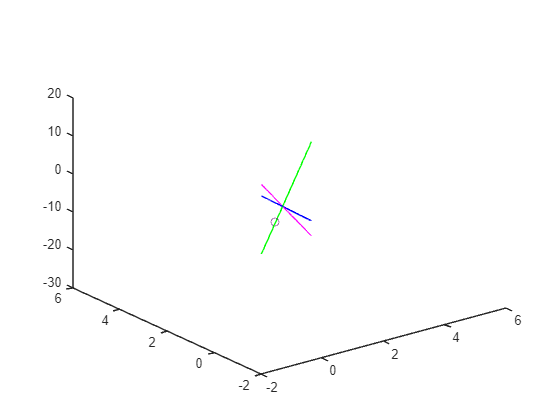

X = -2:0.01:5;
Y = -2:0.01:5;
z1 = 5 - 5*X - Y;
z2 = 6 - 3*X - 4*Y;
z3 = 0 - (2/6)*X - (3/6)*Y;
plot3(X,Y,z1,'b')
hold on
plot3(X,Y,z2,'m')
plot3(X,Y,z3, 'g')
plot3(0,0,0, 'o')
hold off

Implementação Gauss-Jacobi por componente:


$$x_{1}^{(k+1)} = \frac{1}{a_{11}} ( b_{1} - a_{12}x_{2}^{(k)} - a_{13}x_{3}^{(k)})\\
x_{2}^{(k+1)} = \frac{1}{a_{22}} ( b_{2} - a_{21}x_{1}^{(k)} - a_{23}x_{3}^{(k)} )\\
  x_{3}^{(k+1)} = \frac{1}{a_{33}} ( b_{3} - a_{31}x_{1}^{(k)} - a_{32}x_{2}^{(k)})


$$


A = [5 1 1; 3 4 1; 2 3 6];
b = [5; 6; 0];
x0 = zeros(3, 1);
tol = 0.05;
d = 2;
k = 0;
while d > tol
    k = k+1;
    x_1 = ( 1/A(1,1))*(b(1) - A(1,2)*x0(2) - A(1,3)*x0(3));
    x_2 = ( 1/A(2,2))*(b(2) - A(2,1)*x0(1) - A(2,3)*x0(3));
    x_3 = ( 1/A(3,3))*(b(3) - A(3,1)*x0(1) - A(3,2)*x0(2));
    x = [x_1;x_2;x_3];
    xit(k, :)= x;
    d = norm(abs(x - x0), inf);
    dit(k, :) = d;
    x0 = x;
end
xit, dit

xit =     1.0000    1.5000         0
    0.7000    0.7500   -1.0833
    1.0667    1.2458   -0.6083
    0.8725    0.8521   -0.9785
    1.0253    1.0902   -0.7169
    0.9253    0.9103   -0.8869
    0.9953    1.0277   -0.7636
    0.9472    0.9444   -0.8456
    0.9802    1.0010   -0.7879
    0.9574    0.9618   -0.8273


dit =     1.5000
    1.0833
    0.4958
    0.3938
    0.2616
    0.1800
    0.1233
    0.0833
    0.0577
    0.0393


Implementação Gauss-Jacobi matricial


$$x^{k+1} =Cx^{k} + g$$


A = [5 1 1; 3 4 1; 2 3 6];
b = [5;6;0];
x0 = zeros(3,1);
tol = 0.05;
n = length(b);
d = 2;
k = 0;
for i = 1:n
	for j = 1:n
		if i == j
			C(i,j) = 0;
		else
			C(i,j) = A(i,j)/A(i,i);
		end
	end
	g(i) = b(i)/A(i,i);
end
C,g

C =          0    0.2000    0.2000
    0.7500         0    0.2500
    0.3333    0.5000         0


g =     1.0000    1.5000         0






d = 2;
k = 0;
while d > tol
    k = k+1;
    x = C*x0 + g';
    xit(k, :) = x;
    d = norm(abs(x - x0), "inf");
    dit(k, :) = d;
    x0 = x;
end

xit, dit

xit =     1.0000    1.5000         0
    1.3000    2.2500    1.0833
    1.6667    2.7458    1.5583
    1.8608    3.1396    1.9285
    2.0136    3.3777    2.1901
    2.1136    3.5577    2.3601
    2.1836    3.6752    2.4834
    2.2317    3.7585    2.5654
    2.2648    3.8151    2.6232
    2.2877    3.8544    2.6625


dit =     1.5000
    1.0833
    0.4958
    0.3937
    0.2616
    0.1800
    0.1233
    0.0833
    0.0577
    0.0393



A = [5 1 1; 3 4 1; 2 3 6];
alfa1 = (abs(A(1,2)) + abs(A(1,3)))/abs(A(1,1));
alfa2 = (abs(A(2,1)) + abs(A(2,3)))/abs(A(2,2));
alfa3 = (abs(A(3,1)) + abs(A(3,2)))/abs(A(3,3));
alfa = max([alfa1, alfa2, alfa3])

alfa = 1



clear



A = [5 1 1; 3 4 1; 2 3 6];
b = [5; 6; 0];
x0 = zeros(3, 1);
tol = 0.05;
d = 2;
k = 0;
while d > tol
    k = k+1;
    x_1 = ( 1/A(1,1))*(b(1) - A(1,2)*x0(2) - A(1,3)*x0(3));
    x_2 = ( 1/A(2,2))*(b(2) - A(2,1)*x_1 - A(2,3)*x0(3));
    x_3 = ( 1/A(3,3))*(b(3) - A(3,1)*x_1 - A(3,2)*x_2);
    x = [x_1;x_2;x_3];
    xit(k, :)= x;
    d = norm(abs(x - x0), inf);
    dit(k, :) = d;
    x0 = x;
end
xit, dit

xit =     1.0000    0.7500   -0.7083
    0.9917    0.9333   -0.7972
    0.9728    0.9697   -0.8091


dit =     1.0000
    0.1833
    0.0364


### **Método De Gauss-Seidel**


$$x_{1}^{(k+1)} = \frac{1}{a_{11}} ( b_{1} - a_{12}x_{2}^{(k)} - a_{13}x_{3}^{(k)} - \cdots - a_{1n}x_{n}^{(k)})\\
x_{2}^{(k+1)} = \frac{1}{a_{22}} ( b_{2} - a_{21}x_{1}^{(k+1)} - a_{23}x_{3}^{(k)} - \cdots - a_{2n}x_{n}^{(k)})\\
  x_{3}^{(k+1)} = \frac{1}{a_{33}} ( b_{3} - a_{31}x_{1}^{(k+1)} - a_{32}x_{2}^{(k+1)} - \cdots - a_{3n}x_{n}^{(k)})\\
  \vdots               = \vdots \\
  x_{n}^{(k+1)}=  \frac{1}{a_{nn}} ( b_{n} - a_{n1}x_{1}^{(k+1)} - a_{n2}x_{2}^{(k+1)} - \cdots - a_{n,n-1}x_{n-1}^{(k+1)})
$$


Vamos encontrar a solução aproximada do sistema 


$$\begin{cases}
5x_{1} + x_{2} + x_{3} = 5\\
3x_{1} + 4x_{2} + x_{3} = 6\\
2x_{1} + 3x_{2} + 6x_{3} = 0
\end{cases}$$


com chute inicial $x^{0} = (0,0,0)$ e $\epsilon=0.05$.